clf
clear all
X_positions = []


X_positions =

     []



Y_positions = []


Y_positions =

     []



Z_positions = []


Z_positions =

     []



robot_positions = []


robot_positions =

     []



position_errors = []


position_errors =

     []



folders = ["9","118","205","280","333","411","425"]

folders = 1×7 string array
    "9"    "118"    "205"    "280"    "333"    "411"    "425"


mean_robot_positions = []


mean_robot_positions =

     []



position_deviations = []


position_deviations =

     []



for j = 1:length(folders)
    robot_positions = []
    position_cloud = []
    prefix = folders(j)
    for i =1 : 3
        name = 'pt '+prefix+'\robot_motion_pt_'+prefix+'_' +string(i)+'.bag'
        bag = rosbag(name);
    
        bSel = select(bag,'Topic','/tool_link_ee_pose')
        % 
        msgStructs = readMessages(bSel,'DataFormat','struct');
        
        X = msgStructs{bSel.NumMessages,1}.Transform.Translation.X;
        Y = msgStructs{bSel.NumMessages,1}.Transform.Translation.Y
        Z = msgStructs{bSel.NumMessages,1}.Transform.Translation.Z;
        robot_positions = [robot_positions;X Y Z]
        
        
        name = 'pt '+prefix+'/pose_normal_pt_'+prefix+'_'+string(i)+'.bag'
        bag = rosbag(name);
        
        bSel = select(bag,'Topic','/tf_array_out');
        msgStructs = readMessages(bSel,'DataFormat','struct');
        x = msgStructs{bSel.NumMessages,1}.Poses.Position.X;
        y = msgStructs{bSel.NumMessages,1}.Poses.Position.Y;
        z = msgStructs{bSel.NumMessages,1}.Poses.Position.Z;
        
        position_cloud = [position_cloud ; x y z]
        
        
    %     error_orientation = abs(robot_orientation_euler_deg -mean_rpy)
        
        
    end
    error_position = mean(robot_positions - position_cloud)
    position_errors = [position_errors;error_position]
    std_error_position = std(robot_positions - position_cloud)*1000
    position_deviations = [position_deviations;std_error_position]
end


robot_positions =

     []




position_cloud =

     []



prefix = "9"

name = "pt 9\robot_motion_pt_9_1.bag"

bSel =   BagSelection with properties:

           FilePath: 'C:\Users\shrut\OneDrive\Documents\MATLAB\Tests_12.10_mannequin\Tests_12.10\pt 9\robot_motion_pt_9_1.bag'
          StartTime: 1.6969e+09
            EndTime: 1.6969e+09
        NumMessages: 1244
    AvailableTopics: [1×3 table]
    AvailableFrames: {0×1 cell}
        MessageList: [1244×4 table]


Y = 0.0175

robot_positions =    -0.7068    0.0175    0.0862


name = "pt 9/pose_normal_pt_9_1.bag"

position_cloud =    -0.7048    0.0210    0.0869


name = "pt 9\robot_motion_pt_9_2.bag"

bSel =   BagSelection with properties:

           FilePath: 'C:\Users\shrut\OneDrive\Documents\MATLAB\Tests_12.10_mannequin\Tests_12.10\pt 9\robot_motion_pt_9_2.bag'
          StartTime: 1.6969e+09
            EndTime: 1.6969e+09
        NumMessages: 798
    AvailableTopics: [1×3 table]
    AvailableFrames: {0×1 cell}
        MessageList: [798×4 table]


Y = 0.0228

robot_positions =    -0.7068    0.0175    0.0862
   -0.6933    0.0228    0.0847


name = "pt 9/pose_normal_pt_9_2.bag"

position_cloud =    -0.7048    0.0210    0.0869
   -0.7041    0.0218    0.0863


name = "pt 9\robot_motion_pt_9_3.bag"

bSel =   BagSelection with properties:

           FilePath: 'C:\Users\shrut\OneDrive\Documents\MATLAB\Tests_12.10_mannequin\Tests_12.10\pt 9\robot_motion_pt_9_3.bag'
          StartTime: 1.6969e+09
            EndTime: 1.6969e+09
        NumMessages: 1185
    AvailableTopics: [1×3 table]
    AvailableFrames: {0×1 cell}
        MessageList: [1185×4 table]


Y = 0.0239

robot_positions =    -0.7068    0.0175    0.0862
   -0.6933    0.0228    0.0847
   -0.6933    0.0239    0.0856


name = "pt 9/pose_normal_pt_9_3.bag"

position_cloud =    -0.7048    0.0210    0.0869
   -0.7041    0.0218    0.0863
   -0.7042    0.0212    0.0876


error_position =     0.0066    0.0001   -0.0014


position_errors =     0.0066    0.0001   -0.0014


std_error_position =     7.3999    3.2666    0.6315


position_deviations =     7.3999    3.2666    0.6315



robot_positions =

     []




position_cloud =

     []



prefix = "118"

name = "pt 118\robot_motion_pt_118_1.bag"

bSel =   BagSelection with properties:

           FilePath: 'C:\Users\shrut\OneDrive\Documents\MATLAB\Tests_12.10_mannequin\Tests_12.10\pt 118\robot_motion_pt_118_1.bag'
          StartTime: 1.6971e+09
            EndTime: 1.6971e+09
        NumMessages: 1007
    AvailableTopics: [1×3 table]
    AvailableFrames: {0×1 cell}
        MessageList: [1007×4 table]


Y = -0.0247

robot_positions =    -0.6786   -0.0247    0.0945


name = "pt 118/pose_normal_pt_118_1.bag"

position_cloud =    -0.6815   -0.0305    0.0988


name = "pt 118\robot_motion_pt_118_2.bag"

bSel =   BagSelection with properties:

           FilePath: 'C:\Users\shrut\OneDrive\Documents\MATLAB\Tests_12.10_mannequin\Tests_12.10\pt 118\robot_motion_pt_118_2.bag'
          StartTime: 1.6971e+09
            EndTime: 1.6971e+09
        NumMessages: 827
    AvailableTopics: [1×3 table]
    AvailableFrames: {0×1 cell}
        MessageList: [827×4 table]


Y = -0.0249

robot_positions =    -0.6786   -0.0247    0.0945
   -0.6787   -0.0249    0.0939


name = "pt 118/pose_normal_pt_118_2.bag"

position_cloud =    -0.6815   -0.0305    0.0988
   -0.6823   -0.0314    0.0981


name = "pt 118\robot_motion_pt_118_3.bag"

bSel =   BagSelection with properties:

           FilePath: 'C:\Users\shrut\OneDrive\Documents\MATLAB\Tests_12.10_mannequin\Tests_12.10\pt 118\robot_motion_pt_118_3.bag'
          StartTime: 1.6971e+09
            EndTime: 1.6971e+09
        NumMessages: 1102
    AvailableTopics: [1×3 table]
    AvailableFrames: {0×1 cell}
        MessageList: [1102×4 table]


Y = -0.0264

robot_positions =    -0.6786   -0.0247    0.0945
   -0.6787   -0.0249    0.0939
   -0.6786   -0.0264    0.0929


name = "pt 118/pose_normal_pt_118_3.bag"

position_cloud =    -0.6815   -0.0305    0.0988
   -0.6823   -0.0314    0.0981
   -0.6817   -0.0300    0.0989


error_position =     0.0032    0.0053   -0.0048


position_errors =     0.0066    0.0001   -0.0014
    0.0032    0.0053   -0.0048


std_error_position =     0.3800    1.4832    1.0653


position_deviations =     7.3999    3.2666    0.6315
    0.3800    1.4832    1.0653



robot_positions =

     []




position_cloud =

     []



prefix = "205"

name = "pt 205\robot_motion_pt_205_1.bag"

bSel =   BagSelection with properties:

           FilePath: 'C:\Users\shrut\OneDrive\Documents\MATLAB\Tests_12.10_mannequin\Tests_12.10\pt 205\robot_motion_pt_205_1.bag'
          StartTime: 1.6969e+09
            EndTime: 1.6969e+09
        NumMessages: 866
    AvailableTopics: [1×3 table]
    AvailableFrames: {0×1 cell}
        MessageList: [866×4 table]


Y = -0.0058

robot_positions =    -0.6699   -0.0058    0.0770


name = "pt 205/pose_normal_pt_205_1.bag"

position_cloud =    -0.6759   -0.0164    0.0770


name = "pt 205\robot_motion_pt_205_2.bag"

bSel =   BagSelection with properties:

           FilePath: 'C:\Users\shrut\OneDrive\Documents\MATLAB\Tests_12.10_mannequin\Tests_12.10\pt 205\robot_motion_pt_205_2.bag'
          StartTime: 1.6969e+09
            EndTime: 1.6969e+09
        NumMessages: 906
    AvailableTopics: [1×3 table]
    AvailableFrames: {0×1 cell}
        MessageList: [906×4 table]


Y = -0.0057

robot_positions =    -0.6699   -0.0058    0.0770
   -0.6688   -0.0057    0.0766


name = "pt 205/pose_normal_pt_205_2.bag"

position_cloud =    -0.6759   -0.0164    0.0770
   -0.6761   -0.0165    0.0795


name = "pt 205\robot_motion_pt_205_3.bag"

bSel =   BagSelection with properties:

           FilePath: 'C:\Users\shrut\OneDrive\Documents\MATLAB\Tests_12.10_mannequin\Tests_12.10\pt 205\robot_motion_pt_205_3.bag'
          StartTime: 1.6969e+09
            EndTime: 1.6969e+09
        NumMessages: 801
    AvailableTopics: [1×3 table]
    AvailableFrames: {0×1 cell}
        MessageList: [801×4 table]


Y = -0.0059

robot_positions =    -0.6699   -0.0058    0.0770
   -0.6688   -0.0057    0.0766
   -0.6687   -0.0059    0.0771


name = "pt 205/pose_normal_pt_205_3.bag"

position_cloud =    -0.6759   -0.0164    0.0770
   -0.6761   -0.0165    0.0795
   -0.6761   -0.0167    0.0793


error_position =     0.0069    0.0107   -0.0017


position_errors =     0.0066    0.0001   -0.0014
    0.0032    0.0053   -0.0048
    0.0069    0.0107   -0.0017


std_error_position =     0.8556    0.1300    1.5456


position_deviations =     7.3999    3.2666    0.6315
    0.3800    1.4832    1.0653
    0.8556    0.1300    1.5456



robot_positions =

     []




position_cloud =

     []



prefix = "280"

name = "pt 280\robot_motion_pt_280_1.bag"

bSel =   BagSelection with properties:

           FilePath: 'C:\Users\shrut\OneDrive\Documents\MATLAB\Tests_12.10_mannequin\Tests_12.10\pt 280\robot_motion_pt_280_1.bag'
          StartTime: 1.6971e+09
            EndTime: 1.6971e+09
        NumMessages: 722
    AvailableTopics: [1×3 table]
    AvailableFrames: {0×1 cell}
        MessageList: [722×4 table]


Y = 0.0493

robot_positions =    -0.6954    0.0493    0.1002


name = "pt 280/pose_normal_pt_280_1.bag"

position_cloud =    -0.6970    0.0517    0.0961


name = "pt 280\robot_motion_pt_280_2.bag"

bSel =   BagSelection with properties:

           FilePath: 'C:\Users\shrut\OneDrive\Documents\MATLAB\Tests_12.10_mannequin\Tests_12.10\pt 280\robot_motion_pt_280_2.bag'
          StartTime: 1.6971e+09
            EndTime: 1.6971e+09
        NumMessages: 969
    AvailableTopics: [1×3 table]
    AvailableFrames: {0×1 cell}
        MessageList: [969×4 table]


Y = 0.0497

robot_positions =    -0.6954    0.0493    0.1002
   -0.6953    0.0497    0.1003


name = "pt 280/pose_normal_pt_280_2.bag"

position_cloud =    -0.6970    0.0517    0.0961
   -0.6966    0.0519    0.0961


name = "pt 280\robot_motion_pt_280_3.bag"

bSel =   BagSelection with properties:

           FilePath: 'C:\Users\shrut\OneDrive\Documents\MATLAB\Tests_12.10_mannequin\Tests_12.10\pt 280\robot_motion_pt_280_3.bag'
          StartTime: 1.6971e+09
            EndTime: 1.6971e+09
        NumMessages: 709
    AvailableTopics: [1×3 table]
    AvailableFrames: {0×1 cell}
        MessageList: [709×4 table]


Y = 0.0491

robot_positions =    -0.6954    0.0493    0.1002
   -0.6953    0.0497    0.1003
   -0.6948    0.0491    0.1005


name = "pt 280/pose_normal_pt_280_3.bag"

position_cloud =    -0.6970    0.0517    0.0961
   -0.6966    0.0519    0.0961
   -0.6970    0.0519    0.0960


error_position =     0.0017   -0.0025    0.0042


position_errors =     0.0066    0.0001   -0.0014
    0.0032    0.0053   -0.0048
    0.0069    0.0107   -0.0017
    0.0017   -0.0025    0.0042


std_error_position =     0.4675    0.3092    0.1675


position_deviations =     7.3999    3.2666    0.6315
    0.3800    1.4832    1.0653
    0.8556    0.1300    1.5456
    0.4675    0.3092    0.1675



robot_positions =

     []




position_cloud =

     []



prefix = "333"

name = "pt 333\robot_motion_pt_333_1.bag"

bSel =   BagSelection with properties:

           FilePath: 'C:\Users\shrut\OneDrive\Documents\MATLAB\Tests_12.10_mannequin\Tests_12.10\pt 333\robot_motion_pt_333_1.bag'
          StartTime: 1.6971e+09
            EndTime: 1.6971e+09
        NumMessages: 618
    AvailableTopics: [1×3 table]
    AvailableFrames: {0×1 cell}
        MessageList: [618×4 table]


Y = 0.0498

robot_positions =    -0.7532    0.0498    0.1083


name = "pt 333/pose_normal_pt_333_1.bag"

position_cloud =    -0.7425    0.0534    0.1031


name = "pt 333\robot_motion_pt_333_2.bag"

bSel =   BagSelection with properties:

           FilePath: 'C:\Users\shrut\OneDrive\Documents\MATLAB\Tests_12.10_mannequin\Tests_12.10\pt 333\robot_motion_pt_333_2.bag'
          StartTime: 1.6971e+09
            EndTime: 1.6971e+09
        NumMessages: 697
    AvailableTopics: [1×3 table]
    AvailableFrames: {0×1 cell}
        MessageList: [697×4 table]


Y = 0.0500

robot_positions =    -0.7532    0.0498    0.1083
   -0.7401    0.0500    0.1080


name = "pt 333/pose_normal_pt_333_2.bag"

position_cloud =    -0.7425    0.0534    0.1031
   -0.7433    0.0542    0.1023


name = "pt 333\robot_motion_pt_333_3.bag"

bSel =   BagSelection with properties:

           FilePath: 'C:\Users\shrut\OneDrive\Documents\MATLAB\Tests_12.10_mannequin\Tests_12.10\pt 333\robot_motion_pt_333_3.bag'
          StartTime: 1.6971e+09
            EndTime: 1.6971e+09
        NumMessages: 512
    AvailableTopics: [1×3 table]
    AvailableFrames: {0×1 cell}
        MessageList: [512×4 table]


Y = 0.0496

robot_positions =    -0.7532    0.0498    0.1083
   -0.7401    0.0500    0.1080
   -0.7388    0.0496    0.1082


name = "pt 333/pose_normal_pt_333_3.bag"

position_cloud =    -0.7425    0.0534    0.1031
   -0.7433    0.0542    0.1023
   -0.7426    0.0529    0.1032


error_position =    -0.0012   -0.0037    0.0053


position_errors =     0.0066    0.0001   -0.0014
    0.0032    0.0053   -0.0048
    0.0069    0.0107   -0.0017
    0.0017   -0.0025    0.0042
   -0.0012   -0.0037    0.0053


std_error_position =     8.2178    0.4891    0.3633


position_deviations = 5×3
    7.3999    3.2666    0.6315
    0.3800    1.4832    1.0653
    0.8556    0.1300    1.5456
    0.4675    0.3092    0.1675
    8.2178    0.4891    0.3633



robot_positions =

     []




position_cloud =

     []



prefix = "411"

name = "pt 411\robot_motion_pt_411_1.bag"

bSel =   BagSelection with properties:

           FilePath: 'C:\Users\shrut\OneDrive\Documents\MATLAB\Tests_12.10_mannequin\Tests_12.10\pt 411\robot_motion_pt_411_1.bag'
          StartTime: 1.6969e+09
            EndTime: 1.6969e+09
        NumMessages: 805
    AvailableTopics: [1×3 table]
    AvailableFrames: {0×1 cell}
        MessageList: [805×4 table]


Y = 0.0605

robot_positions = 1×3
   -0.6767    0.0605    0.0795


name = "pt 411/pose_normal_pt_411_1.bag"

position_cloud = 1×3
   -0.6769    0.0692    0.0708


name = "pt 411\robot_motion_pt_411_2.bag"

bSel =   BagSelection with properties:

           FilePath: 'C:\Users\shrut\OneDrive\Documents\MATLAB\Tests_12.10_mannequin\Tests_12.10\pt 411\robot_motion_pt_411_2.bag'
          StartTime: 1.6969e+09
            EndTime: 1.6969e+09
        NumMessages: 830
    AvailableTopics: [1×3 table]
    AvailableFrames: {0×1 cell}
        MessageList: [830×4 table]


Y = 0.0612

robot_positions = 2×3
   -0.6767    0.0605    0.0795
   -0.6764    0.0612    0.0794


name = "pt 411/pose_normal_pt_411_2.bag"

position_cloud = 2×3
   -0.6769    0.0692    0.0708
   -0.6767    0.0691    0.0709


name = "pt 411\robot_motion_pt_411_3.bag"

bSel =   BagSelection with properties:

           FilePath: 'C:\Users\shrut\OneDrive\Documents\MATLAB\Tests_12.10_mannequin\Tests_12.10\pt 411\robot_motion_pt_411_3.bag'
          StartTime: 1.6969e+09
            EndTime: 1.6969e+09
        NumMessages: 631
    AvailableTopics: [1×3 table]
    AvailableFrames: {0×1 cell}
        MessageList: [631×4 table]


Y = 0.0561

robot_positions = 3×3
   -0.6767    0.0605    0.0795
   -0.6764    0.0612    0.0794
   -0.6794    0.0561    0.0863


name = "pt 411/pose_normal_pt_411_3.bag"

position_cloud = 3×3
   -0.6769    0.0692    0.0708
   -0.6767    0.0691    0.0709
   -0.6812    0.0626    0.0788


error_position = 1×3
    0.0007   -0.0077    0.0082


position_errors = 6×3
    0.0066    0.0001   -0.0014
    0.0032    0.0053   -0.0048
    0.0069    0.0107   -0.0017
    0.0017   -0.0025    0.0042
   -0.0012   -0.0037    0.0053
    0.0007   -0.0077    0.0082


std_error_position = 1×3
    0.8677    1.0795    0.6232


position_deviations = 6×3
    7.3999    3.2666    0.6315
    0.3800    1.4832    1.0653
    0.8556    0.1300    1.5456
    0.4675    0.3092    0.1675
    8.2178    0.4891    0.3633
    0.8677    1.0795    0.6232



robot_positions =

     []




position_cloud =

     []



prefix = "425"

name = "pt 425\robot_motion_pt_425_1.bag"

bSel =   BagSelection with properties:

           FilePath: 'C:\Users\shrut\OneDrive\Documents\MATLAB\Tests_12.10_mannequin\Tests_12.10\pt 425\robot_motion_pt_425_1.bag'
          StartTime: 1.6969e+09
            EndTime: 1.6969e+09
        NumMessages: 1269
    AvailableTopics: [1×3 table]
    AvailableFrames: {0×1 cell}
        MessageList: [1269×4 table]


Y = 0.0472

robot_positions = 1×3
   -0.6731    0.0472    0.0841


name = "pt 425/pose_normal_pt_425_1.bag"

position_cloud = 1×3
   -0.6754    0.0543    0.0778


name = "pt 425\robot_motion_pt_425_2.bag"

bSel =   BagSelection with properties:

           FilePath: 'C:\Users\shrut\OneDrive\Documents\MATLAB\Tests_12.10_mannequin\Tests_12.10\pt 425\robot_motion_pt_425_2.bag'
          StartTime: 1.6969e+09
            EndTime: 1.6969e+09
        NumMessages: 972
    AvailableTopics: [1×3 table]
    AvailableFrames: {0×1 cell}
        MessageList: [972×4 table]


Y = 0.0475

robot_positions = 2×3
   -0.6731    0.0472    0.0841
   -0.6741    0.0475    0.0835


name = "pt 425/pose_normal_pt_425_2.bag"

position_cloud = 2×3
   -0.6754    0.0543    0.0778
   -0.6749    0.0539    0.0787


name = "pt 425\robot_motion_pt_425_3.bag"

bSel =   BagSelection with properties:

           FilePath: 'C:\Users\shrut\OneDrive\Documents\MATLAB\Tests_12.10_mannequin\Tests_12.10\pt 425\robot_motion_pt_425_3.bag'
          StartTime: 1.6969e+09
            EndTime: 1.6969e+09
        NumMessages: 790
    AvailableTopics: [1×3 table]
    AvailableFrames: {0×1 cell}
        MessageList: [790×4 table]


Y = 0.0478

robot_positions = 3×3
   -0.6731    0.0472    0.0841
   -0.6741    0.0475    0.0835
   -0.6739    0.0478    0.0837


name = "pt 425/pose_normal_pt_425_3.bag"

position_cloud = 3×3
   -0.6754    0.0543    0.0778
   -0.6749    0.0539    0.0787
   -0.6752    0.0539    0.0785


error_position = 1×3
    0.0015   -0.0066    0.0055


position_errors = 7×3
    0.0066    0.0001   -0.0014
    0.0032    0.0053   -0.0048
    0.0069    0.0107   -0.0017
    0.0017   -0.0025    0.0042
   -0.0012   -0.0037    0.0053
    0.0007   -0.0077    0.0082
    0.0015   -0.0066    0.0055


std_error_position = 1×3
    0.8036    0.5665    0.7744


position_deviations = 7×3
    7.3999    3.2666    0.6315
    0.3800    1.4832    1.0653
    0.8556    0.1300    1.5456
    0.4675    0.3092    0.1675
    8.2178    0.4891    0.3633
    0.8677    1.0795    0.6232
    0.8036    0.5665    0.7744


%b = bar(categorical({'118','280','332','333'})',position_errors*1000,'grouped')
position_errors = position_errors*1000;
b = bar(position_errors,'grouped')

b =   1×3 Bar array:

    Bar    Bar    Bar


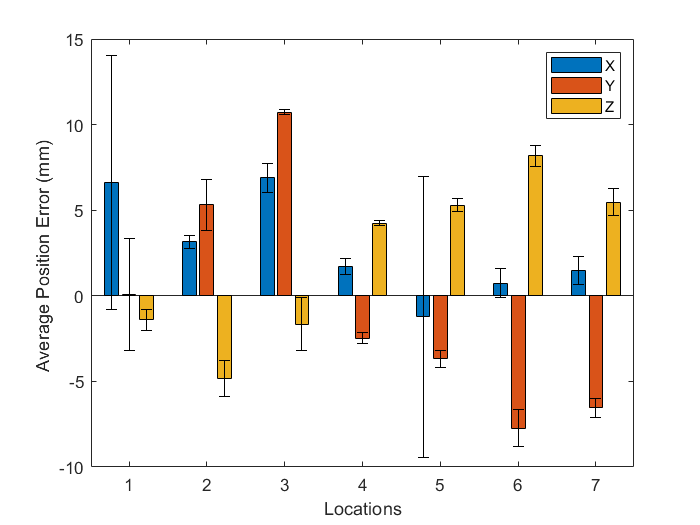

hold on
xlabel("Locations")

ylabel("Average Position Error (mm) ")

%xlabels = categorical({'x 118', 'y 118', 'z 118';'x 280', 'y 280', 'z 280';'x 332', 'y 332', 'z 332' ;'x 333', 'y 333', 'z 333'});
[ngroups,nbars] = size(position_errors);
% Get the x coordinate of the bars
v = nan(nbars, ngroups);
for i = 1:nbars
    v(i,:) = b(i).XEndPoints;
end
% Plot the errorbars
errorbar(v',position_errors,position_deviations,'k','linestyle','none');
hold off

legend(["X","Y","Z"])




clf
X_positions = []


X_positions =

     []



Y_positions = []


Y_positions =

     []



Z_positions = []


Z_positions =

     []



robot_orientation = []


robot_orientation =

     []



std_oreintations_all_tests = []


std_oreintations_all_tests =

     []



error_orientations_all_tests = []


error_orientations_all_tests =

     []



folders = ["9","118","205","280","333","411","425"]

folders = 1×7 string array
    "9"    "118"    "205"    "280"    "333"    "411"    "425"


orientation_error = []


orientation_error =

     []



orientation_error_eul = []


orientation_error_eul =

     []



desired_orientation = []


desired_orientation =

     []



robot_orientations = []


robot_orientations =

     []



for j = 1:length(folders)
    robot_orientations = [];
    position_cloud = [];
    desired_orientation = [];
    prefix = folders(j)
    for i =1 : 3
         
        name = 'pt '+prefix+'\robot_motion_pt_'+prefix+'_' +string(i)+'.bag';
        bag = rosbag(name);
    
        bSel = select(bag,'Topic','/tool_link_ee_pose');
        % 
        msgStructs = readMessages(bSel,'DataFormat','struct');
        
        X = msgStructs{bSel.NumMessages,1}.Transform.Rotation.X;
        Y = msgStructs{bSel.NumMessages,1}.Transform.Rotation.Y;
        Z = msgStructs{bSel.NumMessages,1}.Transform.Rotation.Z;
        W = msgStructs{bSel.NumMessages,1}.Transform.Rotation.W;
        robot_quat = [W X Y Z]
        robot_eul = quat2eul(robot_quat,"ZYX")*180/pi
        %robot_rot_mat = quat2rotm(robot_quat)
        robot_orientations = [robot_orientations;robot_eul]
        
        name = 'pt ' + prefix+'/pose_normal_pt_'+prefix+'_'+string(i)+'.bag';
        bag = rosbag(name);
        
        bSel = select(bag,'Topic','/tf_array_out');
        msgStructs = readMessages(bSel,'DataFormat','struct');
        x = msgStructs{bSel.NumMessages,1}.Poses.Orientation.X;
        y = msgStructs{bSel.NumMessages,1}.Poses.Orientation.Y;
        z = msgStructs{bSel.NumMessages,1}.Poses.Orientation.Z;
        w = msgStructs{bSel.NumMessages,1}.Poses.Orientation.W;
        %desired_rot_mat = quat2rotm([w x y z]);
        desired_eul = quat2eul([w x y z],'ZYX')*180/pi;
        desired_orientation = [desired_orientation;desired_eul]
    end
   orientation_error = desired_orientation - robot_orientations 
   error_orientations_all_tests = [error_orientations_all_tests;mean(orientation_error)]
   std_oreintations_all_tests = [std_oreintations_all_tests;std(orientation_error)]

end

prefix = "9"

robot_quat =    -0.0354    0.7226    0.6884   -0.0515


robot_eul =    87.3153    1.4737 -172.9815


robot_orientations =    87.3153    1.4737 -172.9815


desired_orientation =    87.1076   -0.2928 -172.2183


robot_quat =     0.0147    0.7269    0.6865   -0.0062


robot_eul =    86.7125    1.6723  179.2626


robot_orientations =    87.3153    1.4737 -172.9815
   86.7125    1.6723  179.2626


desired_orientation =    87.1076   -0.2928 -172.2183
   87.1717   -0.6455  177.7150


robot_quat =     0.0163    0.7250    0.6885    0.0030


robot_eul =    87.0313    1.0414  178.4084


robot_orientations =    87.3153    1.4737 -172.9815
   86.7125    1.6723  179.2626
   87.0313    1.0414  178.4084


desired_orientation =    87.1076   -0.2928 -172.2183
   87.1717   -0.6455  177.7150
   87.2753   -1.4270  175.5825


orientation_error =    -0.2077   -1.7665    0.7633
    0.4591   -2.3178   -1.5476
    0.2440   -2.4683   -2.8259


error_orientations_all_tests =     0.1651   -2.1842   -1.2034


std_oreintations_all_tests =     0.3404    0.3695    1.8192


prefix = "118"

robot_quat =    -0.1548    0.7042    0.6806    0.1301


robot_eul =    87.5301  -23.1981 -177.4482


robot_orientations =    87.5301  -23.1981 -177.4482


desired_orientation =    87.6012  -25.2234 -177.7509


robot_quat =    -0.1470    0.7077    0.6791    0.1276


robot_eul =    87.2105  -22.3514 -177.8524


robot_orientations =    87.5301  -23.1981 -177.4482
   87.2105  -22.3514 -177.8524


desired_orientation =    87.6012  -25.2234 -177.7509
   87.2257  -24.7589 -178.0265


robot_quat =    -0.1535    0.7071    0.6782    0.1286


robot_eul =    87.0659  -22.9637 -177.3421


robot_orientations =    87.5301  -23.1981 -177.4482
   87.2105  -22.3514 -177.8524
   87.0659  -22.9637 -177.3421


desired_orientation =    87.6012  -25.2234 -177.7509
   87.2257  -24.7589 -178.0265
   87.2852  -24.5778 -178.3119


orientation_error =     0.0711   -2.0253   -0.3026
    0.0152   -2.4076   -0.1742
    0.2193   -1.6141   -0.9698


error_orientations_all_tests =     0.1651   -2.1842   -1.2034
    0.1019   -2.0157   -0.4822


std_oreintations_all_tests =     0.3404    0.3695    1.8192
    0.1055    0.3968    0.4271


prefix = "205"

robot_quat =    -0.1665    0.7095    0.6750    0.1152


robot_eul =    86.1351  -22.8402 -174.9770


robot_orientations =    86.1351  -22.8402 -174.9770


desired_orientation =    85.9044  -26.8429 -174.4496


robot_quat =    -0.1749    0.7084    0.6746    0.1120


robot_eul =    85.9549  -23.2399 -173.9558


robot_orientations =    86.1351  -22.8402 -174.9770
   85.9549  -23.2399 -173.9558


desired_orientation =    85.9044  -26.8429 -174.4496
   85.8345  -27.6133 -174.0896


robot_quat =    -0.1712    0.7080    0.6757    0.1132


robot_eul =    86.1870  -23.0552 -174.4172


robot_orientations =    86.1351  -22.8402 -174.9770
   85.9549  -23.2399 -173.9558
   86.1870  -23.0552 -174.4172


desired_orientation =    85.9044  -26.8429 -174.4496
   85.8345  -27.6133 -174.0896
   85.9399  -27.2767 -174.1865


orientation_error =    -0.2307   -4.0027    0.5274
   -0.1204   -4.3734   -0.1338
   -0.2472   -4.2215    0.2307


error_orientations_all_tests =     0.1651   -2.1842   -1.2034
    0.1019   -2.0157   -0.4822
   -0.1994   -4.1992    0.2081


std_oreintations_all_tests =     0.3404    0.3695    1.8192
    0.1055    0.3968    0.4271
    0.0689    0.1864    0.3312


prefix = "280"

robot_quat =     0.1316    0.7066    0.6732   -0.1737


robot_eul =    87.9035   24.9999 -176.9695


robot_orientations =    87.9035   24.9999 -176.9695


desired_orientation =    88.7859   25.0720 -176.6479


robot_quat = 1×4
    0.1242    0.7047    0.6770   -0.1721


robot_eul = 1×3
   88.4881   24.2550 -176.3572


robot_orientations = 2×3
   87.9035   24.9999 -176.9695
   88.4881   24.2550 -176.3572


desired_orientation = 2×3
   88.7859   25.0720 -176.6479
   88.7960   25.2578 -176.7209


robot_quat = 1×4
    0.1269    0.7046    0.6768   -0.1714


robot_eul = 1×3
   88.4249   24.4187 -176.6515


robot_orientations = 3×3
   87.9035   24.9999 -176.9695
   88.4881   24.2550 -176.3572
   88.4249   24.4187 -176.6515


desired_orientation = 3×3
   88.7859   25.0720 -176.6479
   88.7960   25.2578 -176.7209
   88.8240   25.6530 -176.6444


orientation_error = 3×3
    0.8824    0.0721    0.3216
    0.3079    1.0028   -0.3637
    0.3991    1.2342    0.0071


error_orientations_all_tests = 4×3
    0.1651   -2.1842   -1.2034
    0.1019   -2.0157   -0.4822
   -0.1994   -4.1992    0.2081
    0.5298    0.7697   -0.0117


std_oreintations_all_tests = 4×3
    0.3404    0.3695    1.8192
    0.1055    0.3968    0.4271
    0.0689    0.1864    0.3312
    0.3087    0.6152    0.3430


prefix = "333"

robot_quat = 1×4
    0.1267    0.7049    0.6767   -0.1707


robot_eul = 1×3
   88.3671   24.3388 -176.7021


robot_orientations = 1×3
   88.3671   24.3388 -176.7021


desired_orientation = 1×3
   88.5575   25.9554 -177.8714


robot_quat = 1×4
    0.1235    0.7051    0.6768   -0.1717


robot_eul = 1×3
   88.4429   24.1622 -176.3309


robot_orientations = 2×3
   88.3671   24.3388 -176.7021
   88.4429   24.1622 -176.3309


desired_orientation = 2×3
   88.5575   25.9554 -177.8714
   88.2774   26.1289 -178.7756


robot_quat = 1×4
    0.1272    0.7067    0.6778   -0.1580


robot_eul = 1×3
   88.0515   23.3071 -177.8528


robot_orientations = 3×3
   88.3671   24.3388 -176.7021
   88.4429   24.1622 -176.3309
   88.0515   23.3071 -177.8528


desired_orientation = 3×3
   88.5575   25.9554 -177.8714
   88.2774   26.1289 -178.7756
   88.6243   25.5215 -177.5028


orientation_error = 3×3
    0.1904    1.6166   -1.1693
   -0.1656    1.9667   -2.4447
    0.5729    2.2144    0.3500


error_orientations_all_tests = 5×3
    0.1651   -2.1842   -1.2034
    0.1019   -2.0157   -0.4822
   -0.1994   -4.1992    0.2081
    0.5298    0.7697   -0.0117
    0.1992    1.9326   -1.0880


std_oreintations_all_tests = 5×3
    0.3404    0.3695    1.8192
    0.1055    0.3968    0.4271
    0.0689    0.1864    0.3312
    0.3087    0.6152    0.3430
    0.3693    0.3003    1.3991


prefix = "411"

robot_quat = 1×4
    0.1209    0.7047    0.6741   -0.1853


robot_eul = 1×3
   88.5718   25.1025 -174.9673


robot_orientations = 1×3
   88.5718   25.1025 -174.9673


desired_orientation = 1×3
   89.5568   27.0236 -174.1273


robot_quat = 1×4
    0.1244    0.7033    0.6729   -0.1926


robot_eul = 1×3
   88.7049   25.9966 -174.6254


robot_orientations = 2×3
   88.5718   25.1025 -174.9673
   88.7049   25.9966 -174.6254


desired_orientation = 2×3
   89.5568   27.0236 -174.1273
   89.6630   27.9065 -173.9871


robot_quat = 1×4
    0.1182    0.7063    0.6767   -0.1710


robot_eul = 1×3
   88.4025   23.6764 -175.9629


robot_orientations = 3×3
   88.5718   25.1025 -174.9673
   88.7049   25.9966 -174.6254
   88.4025   23.6764 -175.9629


desired_orientation = 3×3
   89.5568   27.0236 -174.1273
   89.6630   27.9065 -173.9871
   89.2070   25.8380 -175.6075


orientation_error = 3×3
    0.9851    1.9211    0.8400
    0.9581    1.9099    0.6382
    0.8045    2.1616    0.3553


error_orientations_all_tests = 6×3
    0.1651   -2.1842   -1.2034
    0.1019   -2.0157   -0.4822
   -0.1994   -4.1992    0.2081
    0.5298    0.7697   -0.0117
    0.1992    1.9326   -1.0880
    0.9159    1.9975    0.6112


std_oreintations_all_tests = 6×3
    0.3404    0.3695    1.8192
    0.1055    0.3968    0.4271
    0.0689    0.1864    0.3312
    0.3087    0.6152    0.3430
    0.3693    0.3003    1.3991
    0.0974    0.1422    0.2434


prefix = "425"

robot_quat = 1×4
    0.1334    0.7128    0.6707   -0.1558


robot_eul = 1×3
   86.7578   23.6374 -178.8226


robot_orientations = 1×3
   86.7578   23.6374 -178.8226


desired_orientation = 1×3
   87.5011   25.4679 -178.9364


robot_quat = 1×4
    0.1388    0.7045    0.6736   -0.1750


robot_eul = 1×3
   88.0183   25.6962 -177.4479


robot_orientations = 2×3
   86.7578   23.6374 -178.8226
   88.0183   25.6962 -177.4479


desired_orientation = 2×3
   87.5011   25.4679 -178.9364
   88.9401   27.5917 -176.8410


robot_quat = 1×4
    0.1393    0.7049    0.6749   -0.1678


robot_eul = 1×3
   87.9373   25.1288 -178.0981


robot_orientations = 3×3
   86.7578   23.6374 -178.8226
   88.0183   25.6962 -177.4479
   87.9373   25.1288 -178.0981


desired_orientation = 3×3
   87.5011   25.4679 -178.9364
   88.9401   27.5917 -176.8410
   89.0081   27.8433 -176.6221


orientation_error = 3×3
    0.7433    1.8305   -0.1138
    0.9218    1.8954    0.6069
    1.0708    2.7145    1.4760


error_orientations_all_tests = 7×3
    0.1651   -2.1842   -1.2034
    0.1019   -2.0157   -0.4822
   -0.1994   -4.1992    0.2081
    0.5298    0.7697   -0.0117
    0.1992    1.9326   -1.0880
    0.9159    1.9975    0.6112
    0.9120    2.1468    0.6563


std_oreintations_all_tests = 7×3
    0.3404    0.3695    1.8192
    0.1055    0.3968    0.4271
    0.0689    0.1864    0.3312
    0.3087    0.6152    0.3430
    0.3693    0.3003    1.3991
    0.0974    0.1422    0.2434
    0.1640    0.4927    0.7961



b = bar(error_orientations_all_tests,'grouped')

b =   1×3 Bar array:

    Bar    Bar    Bar


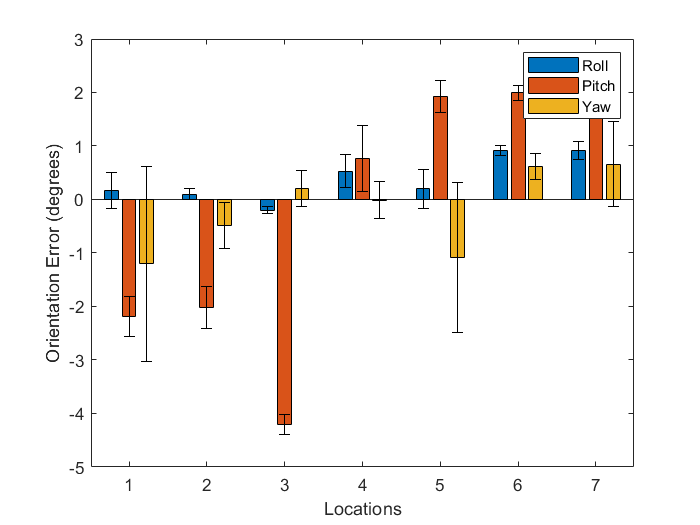

%b = bar(error_orientations_all_tests)
hold on
xlabel("Locations")

ylabel("Orientation Error (degrees)")

%xlabels = categorical({'x 118', 'y 118', 'z 118';'x 280', 'y 280', 'z 280';'x 332', 'y 332', 'z 332' ;'x 333', 'y 333', 'z 333'});
[ngroups,nbars] = size(error_orientations_all_tests);
% Get the x coordinate of the bars
v = nan(nbars, ngroups);
for i = 1:nbars
    v(i,:) = b(i).XEndPoints;
end
% Plot the errorbars
errorbar(v',error_orientations_all_tests,std_oreintations_all_tests,'k','linestyle','none');
hold off
legend(["Roll","Pitch","Yaw"])